close all;
clearvars;
clc;

dir = uigetdir('default','Pilih Folder Data Training');

imds = imageDatastore(dir, ...
    'LabelSource',...
    'foldernames',...
    'IncludeSubfolders',...
    true);

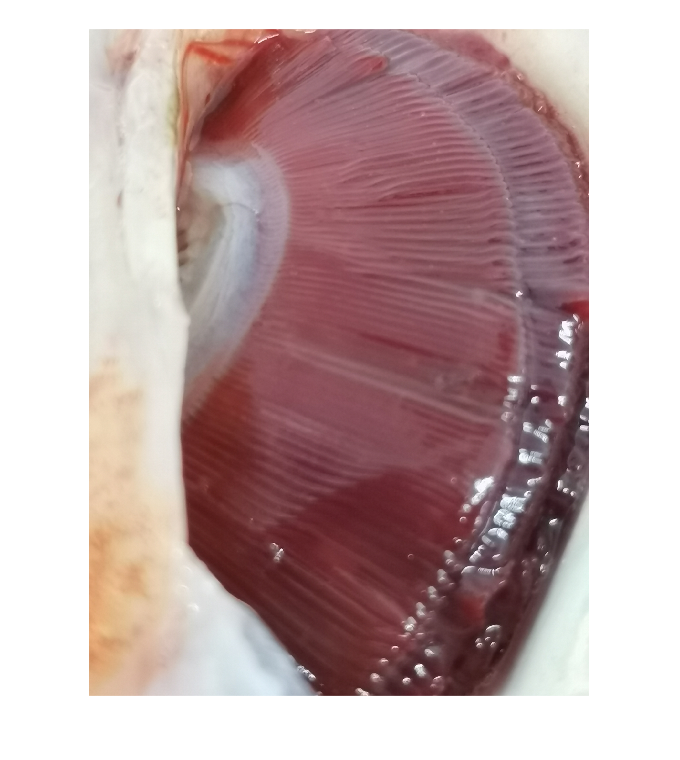

% Find the first instance of an image for each category
segar = find(imds.Labels == 'Segar', 1);

figure
imshow(readimage(imds,segar))

tbl = countEachLabel(imds)

tbl = 2×2 table
       Label       Count
    ___________    _____

    Segar           36  
    Tidak Segar     36  


[trainingSet, testSet] = splitEachLabel(imds, 0.7, 'randomized');


inputSize = [244 244 3];
numClasses = 2;

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
augmentedTrainingSet = augmentedImageDatastore(inputSize, trainingSet, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(inputSize, testSet, 'ColorPreprocessing', 'gray2rgb');

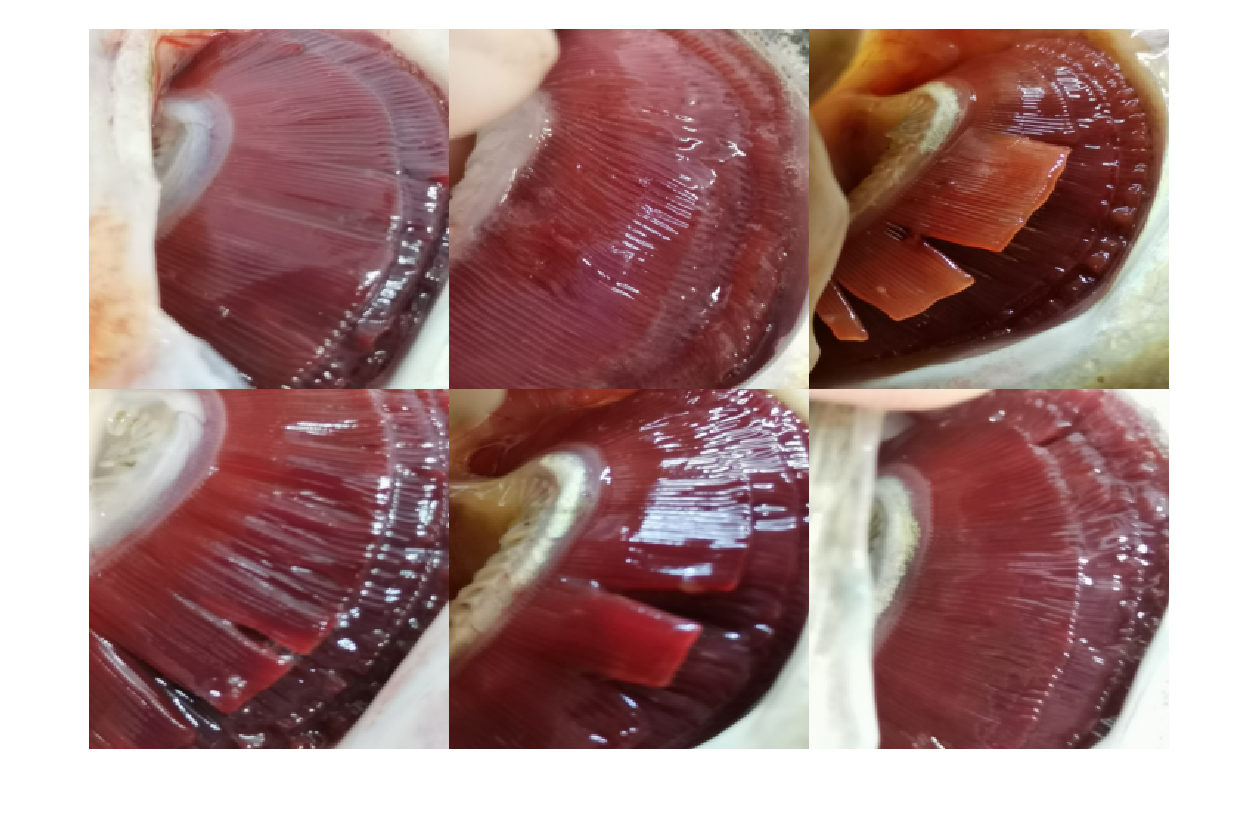

ims = augmentedTrainingSet.preview();
montage(ims{1:6,1})

layers = [
    imageInputLayer(inputSize)
    convolution2dLayer([7 7], 64)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
];

options = trainingOptions('sgdm', ...
    'MaxEpochs',10, ...
    'ValidationData',augmentedTestSet, ...
    'ValidationFrequency',5, ...
    'Verbose',false, ...
    'Plots','training-progress');

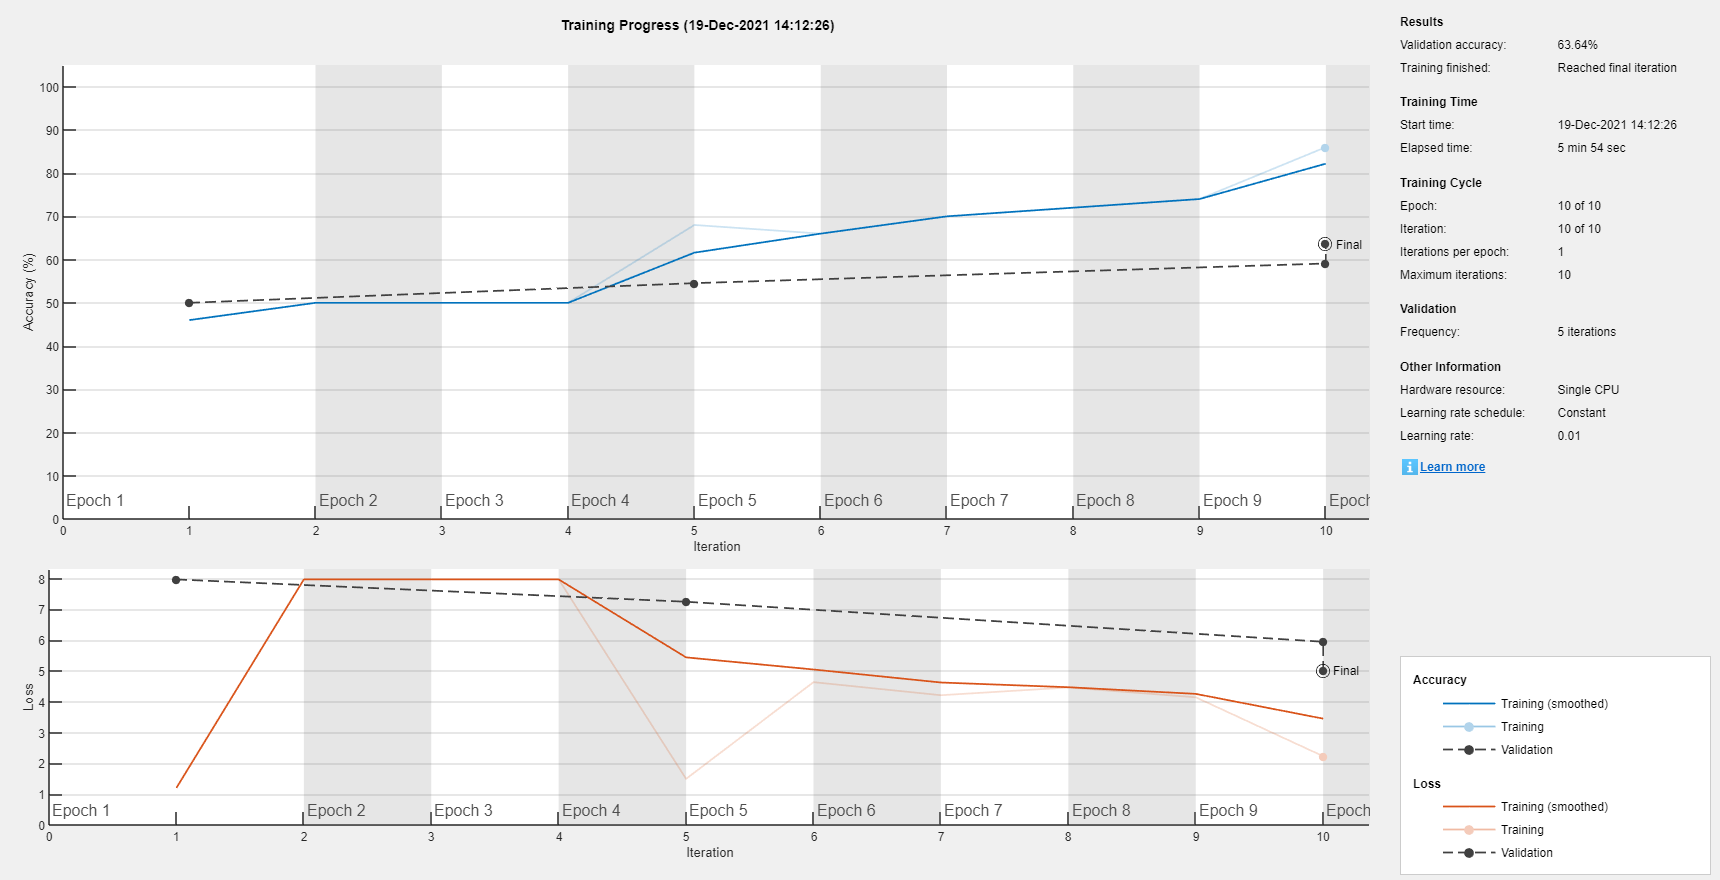

net = trainNetwork(augmentedTrainingSet,layers,options);

Testdir = uigetdir('default','Pilih Folder Data Training');

imdsTest = imageDatastore(dir, ...
    'LabelSource',...
    'foldernames',...
    'IncludeSubfolders',...
    true);
images_num = size(imdsTest.Files,1);

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
TestingSet = augmentedImageDatastore(inputSize, imdsTest, 'ColorPreprocessing', 'gray2rgb');

YPred = classify(net,TestingSet);
YValidation = imdsTest.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.7917

save('network.mat', 'net');